A =     1.0000    1.0000    1.0000    1.0000    1.0000    4.0000
    1.0000    0.8090    0.3090   -0.3090   -0.8090   -4.0000
    1.0000    0.3090   -0.8090   -0.8090    0.3090    4.0000
    1.0000   -0.3090   -0.8090    0.8090    0.3090   -1.0000
    1.0000   -0.8090    0.3090    0.3090   -0.8090    1.0000
    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000


Hd =      0
     0
     0
     1
     1
     1


S =     0.5120
   -0.6472
   -0.0297
    0.2472
    0.0777
   -0.0400


E0 = 0.1501

Fm =          0    0.1250    0.2200    0.2800    0.3560    0.5000


A =     1.0000    1.0000    1.0000    1.0000    1.0000    4.0000
    1.0000    0.7071    0.0000   -0.7071   -1.0000   -4.0000
    1.0000    0.1874   -0.9298   -0.5358    0.7290    4.0000
    1.0000   -0.1874   -0.9298    0.5358    0.7290   -1.0000
    1.0000   -0.6179   -0.2365    0.9101   -0.8881    1.0000
    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000


Hd =      0
     0
     0
     1
     1
     1


S =     0.5018
   -0.6341
   -0.0194
    0.3355
    0.1385
   -0.0806


E0 = 0.0951

Fm =          0    0.1320    0.2200    0.2800    0.3360    0.5000


A =     1.0000    1.0000    1.0000    1.0000    1.0000    4.0000
    1.0000    0.6753   -0.0879   -0.7940   -0.9846   -4.0000
    1.0000    0.1874   -0.9298   -0.5358    0.7290    4.0000
    1.0000   -0.1874   -0.9298    0.5358    0.7290   -1.0000
    1.0000   -0.5144   -0.4707    0.9987   -0.5569    1.0000
    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000


Hd =      0
     0
     0
     1
     1
     1


S =     0.4990
   -0.6268
   -0.0202
    0.3316
    0.1441
   -0.0819


E0 = 0.0821

Fm =          0    0.1320    0.2200    0.2800    0.3340    0.5000


A =     1.0000    1.0000    1.0000    1.0000    1.0000    4.0000
    1.0000    0.6753   -0.0879   -0.7940   -0.9846   -4.0000
    1.0000    0.1874   -0.9298   -0.5358    0.7290    4.0000
    1.0000   -0.1874   -0.9298    0.5358    0.7290   -1.0000
    1.0000   -0.5036   -0.4927    0.9999   -0.5144    1.0000
    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000


Hd =      0
     0
     0
     1
     1
     1


S =     0.4990
   -0.6267
   -0.0203
    0.3316
    0.1442
   -0.0820


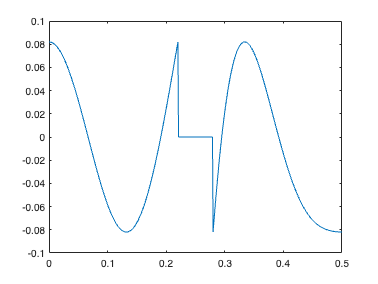

E0 = 0.0820

Fm =          0    0.1320    0.2200    0.2800    0.3340    0.5000


clear;
clc;

N = 9;  % filter length
k = (N - 1)/2; 

W_big = 1;
W_small = 0.25;
delta = 0.001;
F = 0:delta:0.5;

Hd_center = 0.25;
W_high = 0.28;
W_low = 0.22;

h = zeros(k+2,1);
A = zeros(k+2,k+2);
S = zeros(k+2,1);  
Hd = zeros(k+2,1);
W = zeros(k+2,1);
P = []; % extreme points

% for all F
Hd_delta = zeros(size(F,2),1);
W_delta = zeros(size(F,2),1);
err = zeros(size(F,2),1);
R = zeros(size(F,2),1);

E0 = 0;
E1 = inf;

for i = 1:size(F,2)
    if(F(i)<Hd_center)
        Hd_delta(i) = 0;
    else
        Hd_delta(i) = 1;
    end
end


for i = 1:size(F,2)
    if(F(i)<=W_low)
        W_delta(i) = W_small;
    elseif(F(i)>=W_high) 
        W_delta(i) = W_big;
    else % transition band
        W_delta(i) = 0;
    end
end


% step 1
Fm = [0, 0.1, 0.2, 0.3, 0.4, 0.5];

while (E1-E0>delta || E1-E0<0)
    % step 2
    for i = 1:(k+2)
        for j = 1:(k+1)
            A(i,j) = cos(2*pi*(j-1)*Fm(i)); % cos(2*pi*k*F)
        end
    end
    
    
    for i = 1:(k+2)
        if(Fm(i)<=W_low)
            W(i) = W_small;
        elseif(Fm(i)>=W_high) 
            W(i) = W_big;
        else
            W(i) = 0;
        end
    end
    
    
    for i = 1:(k+2)
        A(i,(k+2)) = ((-1)^(i-1))/W(i); % (-1)^(k+1)/W(Fk+1)
    end
    
    
    for i = 1:(k+2)
        if(Fm(i)<Hd_center)
            Hd(i) = 0;
        else
            Hd(i) = 1;
        end
    end
    A
    Hd
    S = inv(A)*Hd   % A^(-1)*b
    
    
    % step 3
    R = zeros(size(F,2),1);
    for i=1:size(F,2)
        for j=1:k+1
            R(i) = R(i)+S(j)*cos(2*pi*(j-1)*F(i));
        end
        err(i) = (R(i)-Hd_delta(i))*W_delta(i);
    end
    plot(F, R, F, Hd_delta)
    plot(F, err)
    
    % step 4
    ex_max = islocalmax(err);
    ex_min = islocalmin(err);

    P = [];
    for i=1:size(F,2)
        if(ex_max(i))
            P = [P, F(i)];
        end
        if(ex_min(i))
            P = [P, F(i)];
        end
    end
   
    if (size(P,2)==k)
        P = [0,P,0.5];
    elseif (size(P,2)==k+1)
        if(err(1)<err(size(F,2)))
            P = [P,0.5];
        else
            P = [0,P];
        end
    else
        disp("!!!!!!!!!!!")
    end
    
    % step 5
    E1 = E0;
    E0 = max(abs(err))
    
    Fm = P
end


% step 6
h(k+1) = S(1);
for i = 1:k
    h(k+i+1) = S(i+1)/2;
    h(k-i+1) = S(i+1)/2;
end
h

h =     0.0721
    0.1658
   -0.0101
   -0.3134
    0.4990
   -0.3134
   -0.0101
    0.1658
    0.0721
